clear all;
close all
clc; clf;

Opgave 2

expFunc = @(x) x*exp(-x^2);

maxn = 5

maxn = 5

for i = 1:maxn
    k = 10^i;
    oppervlakten(i) = samtrap(expFunc,0,1,k);
end
display(oppervlakten)

oppervlakten =     0.3149    0.3160    0.3161    0.3161    0.3161



exact = (1-exp(-1))/2;
relfout = abs(exact-oppervlakten)/abs(exact)

relfout =     0.0036    0.0000    0.0000    0.0000    0.0000


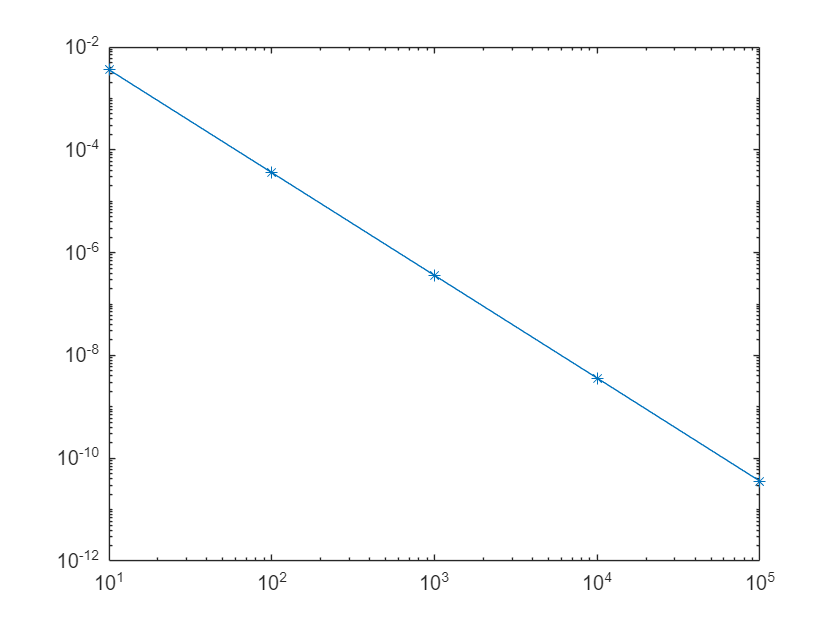


figure(1);clf;
loglog(10.^(1:maxn),relfout,'*-');

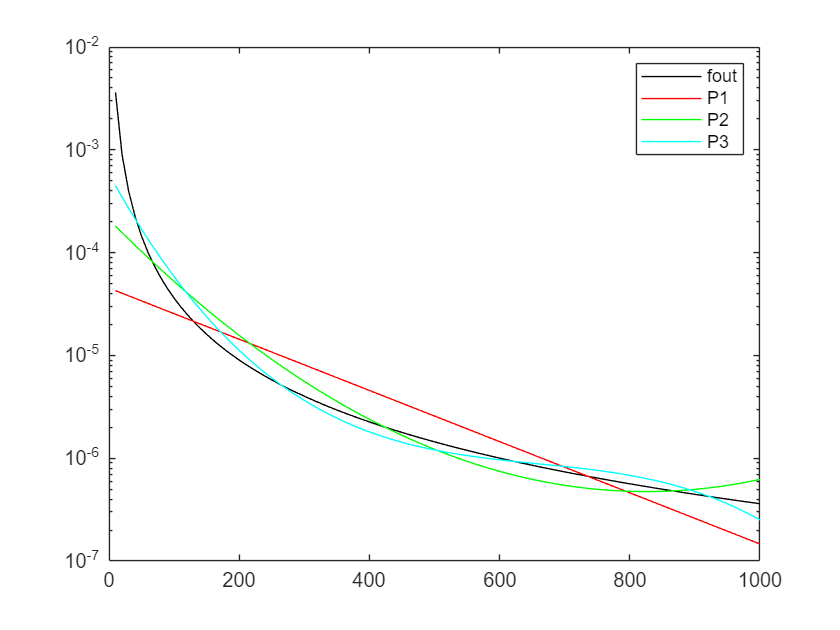


% Afleiding orde van de fout: 
% h is evenredig met 1/k. Als de orde O(h^2) is, is de relatieve fout
%   rel_fout = O(h^2) = O(k^{-2}) voor k groot (of h klein)
% Volgens de definitie van O-notatie
%   rel_fout <= Ak^{-2} voor een zekere constante A als k groot genoeg.
% Dus
% log(rel_fout) <= -2 log k + log(A) = -2 n + log(A)
% Als we de relatieve fout uitzetten in functie van n voor een
% methode van O(h^2) = O(k^{-2}), is de relatieve fout begrensd door een
% rechte met richtingscoefficient -2, en dit voor voldoende grote n.

figure(2);clf;
for i = 1:100
    k = 10*i;
    x(i) = k; 
    y(i) = samtrap(expFunc,0,1,k); % oproep m.b.v anonieme functie
end
relfout= abs(exact-y)/abs(exact); % relatieve fouten
semilogy(x,relfout,'k'); % plot met logaritmische schaal
hold on;

P1 = polyfit(x,log10(relfout),1); % Bereken coefficienten van veelterm p(n) zodat relfout(n) = 10^(p(n))
semilogy(x,10.^(polyval(P1,x)),'r');

P2 = polyfit(x,log10(relfout),2);
semilogy(x,10.^(polyval(P2,x)),'g');

P3 = polyfit(x,log10(relfout),3);
semilogy(x,10.^(polyval(P3,x)),'c');

legend('fout', 'P1', 'P2', 'P3');

Opgave 3

%%%%%%%%%%%%%%%%%
%% VRAAG 1 & 2 %%
%%%%%%%%%%%%%%%%%
% fprintf('\n-------');
grootte = (50:10:500)';
tijd = zeros(length(grootte),1);

fprintf(strcat(['\nMaximale grootte: ', int2str(grootte(end))]))


Maximale grootte: 500

fprintf('\nBerekening gestart voor grootte ');


Berekening gestart voor grootte 


for i = 1:length(grootte)    
    % Print vooruitgang
    if mod(i, 15) == 0
       fprintf('\n')
    end
    fprintf(strcat([int2str(grootte(i)), ', ']))
    
    % Timing lineair stelsel
    T = [];
    for k = 1:1
        T = [T, tijd_linsys(grootte(i))];
    end
    tijd(i) = median(T);
end

50,60,70,80,90,100,110,120,130,140,150,160,170,180,

190,200,210,220,230,240,250,260,270,280,290,300,310,320,330,

340,350,360,370,380,390,400,410,420,430,440,450,460,470,480,

490,500,


figure(1);clf;
plot(grootte,tijd,'k*');
hold on
xlabel('grootte van het stelsel'); ylabel('tijd (sec)')

fprintf('\nKlaar.\n');


Klaar.


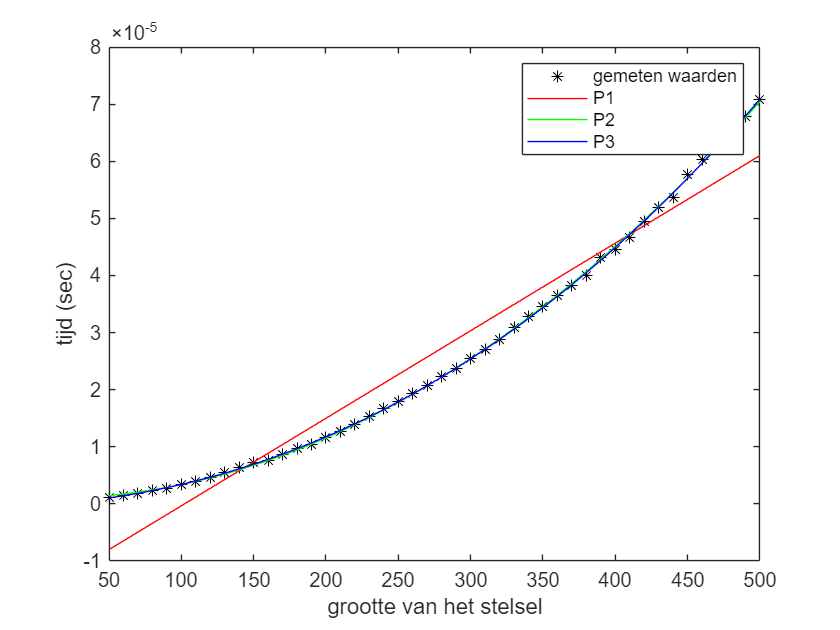


%%%%%%%%%%%%%%%%%
%% VRAAG 3 & 4 %%
%%%%%%%%%%%%%%%%%

P1 = polyfit(grootte, tijd, 1);
P2 = polyfit(grootte, tijd, 2);
P3 = polyfit(grootte, tijd, 3);

tijd1 = polyval(P1,grootte);
tijd2 = polyval(P2,grootte);
tijd3 = polyval(P3,grootte);

plot(grootte,tijd1,'r');
plot(grootte,tijd2,'g');
plot(grootte,tijd3,'b');
legend('gemeten waarden', 'P1', 'P2', 'P3');


variantie1 = sum((tijd-tijd1).^2)/(length(tijd));
variantie2 = sum((tijd-tijd2).^2)/(length(tijd));
variantie3 = sum((tijd-tijd3).^2)/(length(tijd));

fprintf('\nVRAAG 3 & 4: Bepalen van de optimale graad');


VRAAG 3 & 4: Bepalen van de optimale graad

fprintf('\n-------');


-------

fprintf('\nvariantie voor graad 1=%e', variantie1);


variantie voor graad 1=2.044237e-11

fprintf('\nvariantie voor graad 2=%e', variantie2);


variantie voor graad 2=9.780534e-14

fprintf('\nvariantie voor graad 3=%e', variantie3);


variantie voor graad 3=6.801831e-14

fprintf('\n\n');


fprintf('\nDUS: deze test toont dat <tijd> goed benaderd kan worden door een');


DUS: deze test toont dat <tijd> goed benaderd kan worden door een

fprintf('\n     tweedegraads veelterm. Dit bevestigt wat we al wisten, nl. dat');


     tweedegraads veelterm. Dit bevestigt wat we al wisten, nl. dat

fprintf('\n     voorwaartse voor een NxN stelsel O(N^2) rekenwerk/tijd vraagt !');


     voorwaartse voor een NxN stelsel O(N^2) rekenwerk/tijd vraagt !

fprintf('\n\n');


% MERK OP: Graad 2 is optimaal omdat het verschil in variantie van graad 2
% naar graad 3 klein is.
%%%%%%%%%%%%%
%% VRAAG 5 %%
%%%%%%%%%%%%%

fprintf('\nVRAAG 5');


VRAAG 5

fprintf('\n-------');


-------

fprintf('\nUit de vorige vraag onthouden we dat het rekenwerk voor een stelsel met een driehoeksmatrix');


Uit de vorige vraag onthouden we dat het rekenwerk voor een stelsel met een driehoeksmatrix

fprintf('\nO(N^2) is. Concreter:');


O(N^2) is. Concreter:

fprintf('\n    rekenwerk = a0 + a1*N + a2*N^2');


    rekenwerk = a0 + a1*N + a2*N^2

fprintf('\nEr wordt nu gevraagd een ruwe schatting te geven van de rekentijd.');


Er wordt nu gevraagd een ruwe schatting te geven van de rekentijd.

fprintf('\nHet volstaat dan om enkel naar de dominante term te kijken, en');


Het volstaat dan om enkel naar de dominante term te kijken, en

fprintf('\nrekenwerk te benaderen door:');


rekenwerk te benaderen door:

fprintf('\n    rekenwerk ~= a2*N^2');


    rekenwerk ~= a2*N^2

fprintf('\nMerk op dat deze formule geen onmogelijk resultaat geeft voor kleine');


Merk op dat deze formule geen onmogelijk resultaat geeft voor kleine

fprintf('\nstelsels: ');


stelsels: 

fprintf('\n    rekenwerk(0) = 0');


    rekenwerk(0) = 0

fprintf('\nNu moeten we de constante a2 nog bepalen. Daartoe gebruiken we het');


Nu moeten we de constante a2 nog bepalen. Daartoe gebruiken we het

fprintf('\ngegeven dat rekenwerk(1000) = 10');


gegeven dat rekenwerk(1000) = 10

fprintf('\n   a2*(1e3)^2 = 10  ==>  a2 = 1e-5');


   a2*(1e3)^2 = 10  ==>  a2 = 1e-5

fprintf('\nDus, het rekenwerk om een stelsel van grootte 1e4 op te lossen, bedraagt:');


Dus, het rekenwerk om een stelsel van grootte 1e4 op te lossen, bedraagt:

fprintf('\n   rekenwerk = 1e-5 * (1e4)^2 = 1e3 sec = 16.66 minuten');


   rekenwerk = 1e-5 * (1e4)^2 = 1e3 sec = 16.66 minuten

fprintf('\n\n');

